# Forward Kinematic Open Manipulator X

**Define D-H Parameter**

dhparams = [link length(a)    link twist(alpha)    join offset(d)    joint angle(theta)]

dhparams = [0.012   pi/2    0.034   	0;
            0.043   0   0   0;
            0.13   0   0	0;
            0.124   0   0	0
            0.126   0   0   0];
            % Without Torch Welding
            %0       -pi/4       0.6372   0];    % With Torch Welding       


**Define robot configuration and show robot model**

robot = rigidBodyTree;

bodies = cell(5,1);
joints = cell(5,1);
for i = 1:5
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robot,bodies{i},bodies{i-1}.Name)
    end
end

showdetails(robot)

--------------------
Robot: (5 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   
--------------------



joint_angle = struct('JointName', {'jnt1', 'jnt2', 'jnt3', 'jnt4','jnt5'}, ...
                     'JointPosition', {0, (0+pi/2), deg2rad(-10.62), deg2rad(-79.38), 0}) 

joint_angle = 1×5 struct array with fields:
    JointName
    JointPosition


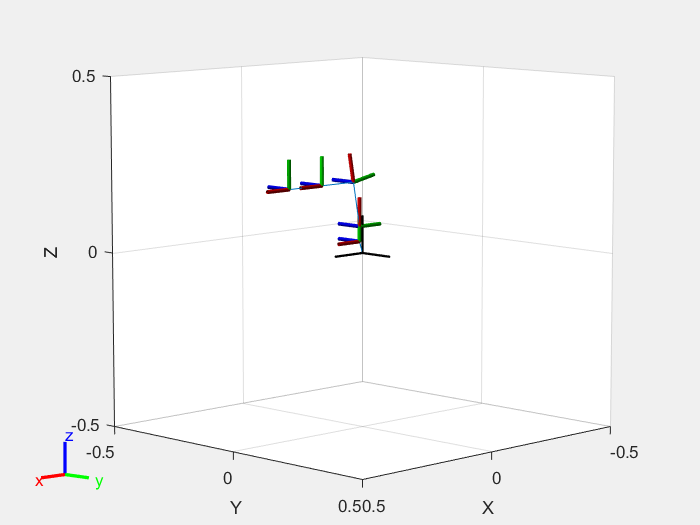


figure(Name="Open Manipulator X")
show(robot,joint_angle);


figure(Name="Open Manipulator X GUI")
%gui = interactiveRigidBodyTree(robot,MarkerScaleFactor=1);



%joint_angle = randomConfiguration(robot)

transform = getTransform(robot,joint_angle,'body5')

transform =     1.0000   -0.0000         0    0.2860
    0.0000    0.0000   -1.0000    0.0000
    0.0000    1.0000    0.0000    0.2048
         0         0         0    1.0000
